clear all; clc;
load("C:\Users\BLooDek\Desktop\numerical-methods\series.mat");


n(ID) = series_NumerMeth(ID);
if n(ID) < 4
n(ID) = 4;
end

if n(ID) > 6
n(ID) = 6;
end
nn = n(ID);

for k = 1:n(ID)
c(k) = ((-1)^series_NumerMeth(ID - 1 + k))*series_NumerMeth(ID + 4 + k);
end

f = @(x)  8*x.^5 + 6*x.^4 + 8*x.^3 - 6*x.^2 - 4*x + 7

f = function_handle with value:
    @(x)8*x.^5+6*x.^4+8*x.^3-6*x.^2-4*x+7


syms x
f1 = diff(f,x)

$$f1 = 40\,x^{4}+24\,x^{3}+24\,x^{2}-12\,x-4$$

f1 = matlabFunction(f1)

f1 = function_handle with value:
    @(x)x.*-1.2e+1+x.^2.*2.4e+1+x.^3.*2.4e+1+x.^4.*4.0e+1-4.0


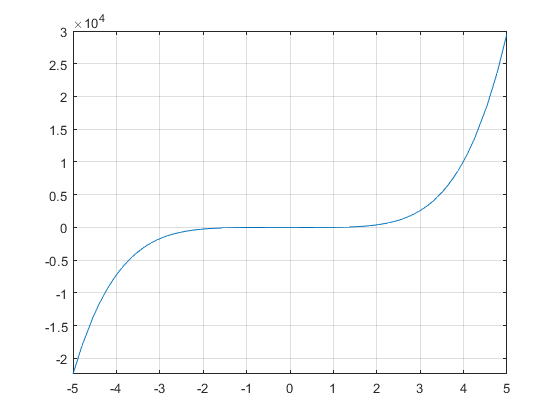


figure;
fplot(f)
grid;

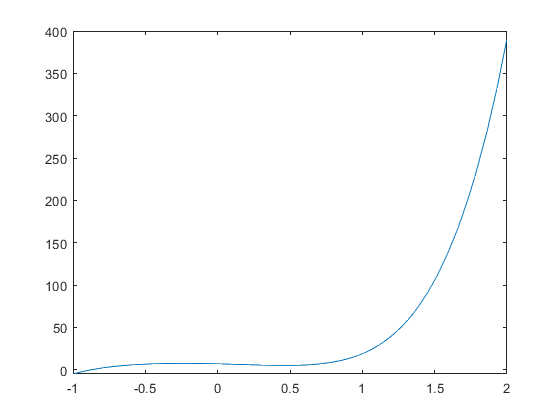



[root1, ite] = NumerMeth_tasks_01_02(f, f1, -1 , 0.01, 50);
[root2, ite] = NumerMeth_tasks_01_02(f, f1, -2 , 0.01, 1000);
[root3, ite] = NumerMeth_tasks_01_02(f, f1, 1 , 0.01, 1000);
fplot(f,[-1 2])

[root4, ite] = NumerMeth_tasks_01_02(f, f1, 2 , 0.01, 1000);